**Practical Problems 4 – Errors & Bracketed Root Finding**	

**1.[Overflow Error] **Matlab returns **Inf** when an overflow error in double precision is encountered. Write a script that starts with *n* = 1, calculates *n*! and increases *n* until overflow occurs (number is too big that Matlab can’t handle it). Display the value of *n* that represents the largest factorial that Matlab can handle.	 	 	 	

n = 1;
factoria_result = 1;
while isfinite(factoria_result)
    n = n + 1;
    factoria_result = factorial(n);
end
largest_n = n - 1;
disp(['Largest n before overflow: ', num2str(largest_n)]);

Largest n before overflow: 170


**2.[Rounding Error]** Approximate the sequence {*π**n*} for *n* = 1 to 18 by rounding π to 1, 2, 4, and 8 decimal places. Calculate the absolute error for each sequence approximation from the sequence that uses *π *with double precision. Plot the errors for each approximate sequence on the same plot with y-axis between 0 and 5. See if you can figure out how to embed smaller plots within the main plot that zoom in on each of the sequences. 	

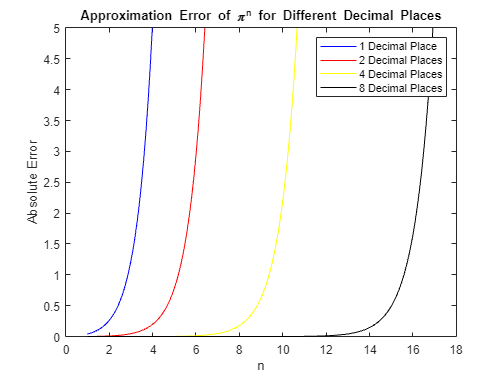

n = 1:0.1:18;
pi_round_value = [round(pi, 1), round(pi, 2), round(pi, 4), round(pi, 8)];
colors = ['b', 'r', 'y', 'k'];
pi_true_value = pi .^ n;

figure;
for i = 1:length(pi_round_value)
    pi_value = pi_round_value(i);
    error = abs((pi_value .^ n) - pi_true_value);
    plot(n, error, colors(i));
    hold on;
end

hold off;
xlabel('n');
ylabel('Absolute Error');
ylim([0 5]);
title('Approximation Error of \pi^n for Different Decimal Places');
legend('1 Decimal Place', '2 Decimal Places', '4 Decimal Places', '8 Decimal Places');

**3.[Truncation Error]** The Maclaurin series for cos(*x*) is                                       

Plot the cosine function in a thick black line between –2π and 2π. On the same graph plot the Maclaurin series approximation for *n* equal to 2, 4, 8 and 16.	 	

x = (-2*pi):0.01:(2*pi)

x =    -6.2832   -6.2732   -6.2632   -6.2532   -6.2432   -6.2332   -6.2232   -6.2132   -6.2032   -6.1932   -6.1832   -6.1732   -6.1632   -6.1532   -6.1432   -6.1332   -6.1232   -6.1132   -6.1032   -6.0932   -6.0832   -6.0732   -6.0632   -6.0532   -6.0432   -6.0332   -6.0232   -6.0132   -6.0032   -5.9932   -5.9832   -5.9732   -5.9632   -5.9532   -5.9432   -5.9332   -5.9232   -5.9132   -5.9032   -5.8932   -5.8832   -5.8732   -5.8632   -5.8532   -5.8432   -5.8332   -5.8232   -5.8132   -5.8032   -5.7932


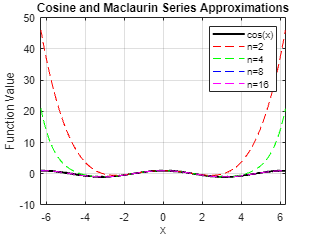


% approx_n2 = 1 - x.^2 / factorial(2);
% approx_n4 = 1 - x.^2 / factorial(2) + x.^4 / factorial(4);
% approx_n8 = 1 - x.^2 / factorial(2) + x.^4 / factorial(4) - x.^6 / factorial(6) + x.^8 / factorial(8);
% approx_n16 = 1 - x.^2 / factorial(2) + x.^4 / factorial(4) - x.^6 / factorial(6) + x.^8 / factorial(8) - x.^10 / factorial(10) + x.^12 / factorial(12) - x.^14 / factorial(14) + x.^16 / factorial(16);

approx_n2 = Maclaurin(2, x);
approx_n4 = Maclaurin(4, x);
approx_n8 = Maclaurin(8, x);
approx_n16 = Maclaurin(16, x);

figure;
plot(x, cos(x), 'k', 'LineWidth', 2);
hold on;
plot(x, approx_n2, 'r--');
plot(x, approx_n4, 'g--');
plot(x, approx_n8, 'b--');
plot(x, approx_n16, 'm--');

xlabel('x');
ylabel('Function Value');
title('Cosine and Maclaurin Series Approximations');
legend('cos(x)', 'n=2', 'n=4', 'n=8', 'n=16');
grid on;
hold off;

**4.[Correcting Measurement Data]** Import the data from the file **data_pp4_q4.xls** using the import wizard (or using the **xlsread** command) then plot the Data against Time. The data should be corrected so that all values above 100 are normalised to exactly 100, and all values below –100 are normalised to exactly –100. Plot the corrected data on a subplot below the original.	 	

**5.[True vs. Relative Error]** The Maclaurin series for *e^x* is                                                     Plot the true function from 0 to 5 then on the same graph plot the Maclaurin approximations for *n* equal to 1, 2, 4, 8, and 16. Calculate the true absolute and true relative errors then plot these together in a separate graph.	 	 	

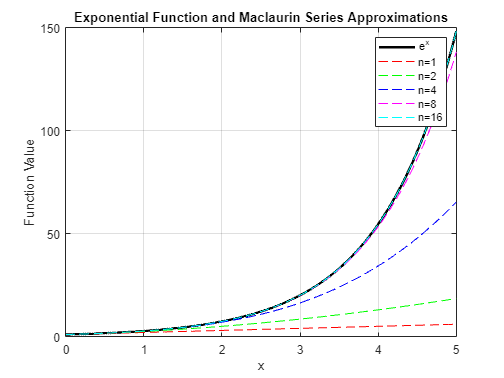

x = linspace(0, 5, 1000); % Generate x values

% Calculate the true exponential function and its Maclaurin approximations
exponential = exp(x);
approx_n1 = 1 + x;
approx_n2 = 1 + x + x.^2 / factorial(2);
approx_n4 = 1 + x + x.^2 / factorial(2) + x.^3 / factorial(3) + x.^4 / factorial(4);
approx_n8 = 1 + x + x.^2 / factorial(2) + x.^3 / factorial(3) + x.^4 / factorial(4) + x.^5 / factorial(5) + x.^6 / factorial(6) + x.^7 / factorial(7) + x.^8 / factorial(8);
approx_n16 = 1 + x + x.^2 / factorial(2) + x.^3 / factorial(3) + x.^4 / factorial(4) + x.^5 / factorial(5) + x.^6 / factorial(6) + x.^7 / factorial(7) + x.^8 / factorial(8) + x.^9 / factorial(9) + x.^10 / factorial(10) + x.^11 / factorial(11) + x.^12 / factorial(12) + x.^13 / factorial(13) + x.^14 / factorial(14) + x.^15 / factorial(15) + x.^16 / factorial(16);

% Plot the true exponential function and its Maclaurin approximations
figure;
plot(x, exponential, 'k', 'LineWidth', 2);
hold on;
plot(x, approx_n1, 'r--');
plot(x, approx_n2, 'g--');
plot(x, approx_n4, 'b--');
plot(x, approx_n8, 'm--');
plot(x, approx_n16, 'c--');

xlabel('x');
ylabel('Function Value');
title('Exponential Function and Maclaurin Series Approximations');
legend('e^x', 'n=1', 'n=2', 'n=4', 'n=8', 'n=16');
grid on;
hold off;

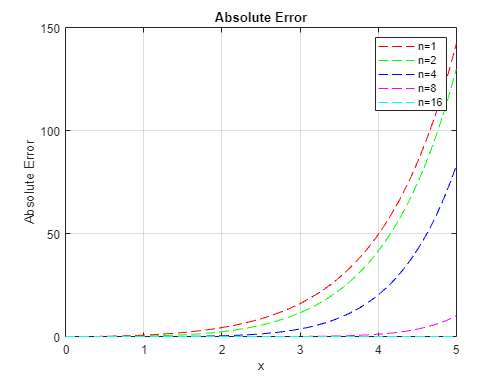


% Calculate true absolute
true_abs_errors_n1 = abs(exponential - approx_n1);
true_abs_errors_n2 = abs(exponential - approx_n2);
true_abs_errors_n4 = abs(exponential - approx_n4);
true_abs_errors_n8 = abs(exponential - approx_n8);
true_abs_errors_n16 = abs(exponential - approx_n16);

figure;
plot(x, true_abs_errors_n1, 'r--');
hold on;
plot(x, true_abs_errors_n2, 'g--');
plot(x, true_abs_errors_n4, 'b--');
plot(x, true_abs_errors_n8, 'm--');
plot(x, true_abs_errors_n16, 'c--');

xlabel('x');
ylabel('Absolute Error');
title('Absolute Error');
legend('n=1', 'n=2', 'n=4', 'n=8', 'n=16');
grid on;
hold off;

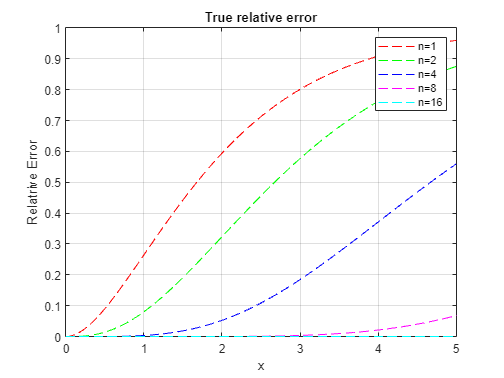


% Calculate relative errors
true_rel_errors_n1 = (exponential - approx_n1) ./ exponential;
true_rel_errors_n2 = (exponential - approx_n2) ./ exponential;
true_rel_errors_n4 = (exponential - approx_n4) ./ exponential;
true_rel_errors_n8 = (exponential - approx_n8) ./ exponential;
true_rel_errors_n16 = (exponential - approx_n16) ./ exponential;

% Plot the relative errors
figure;
plot(x, true_rel_errors_n1, 'r--');
hold on;
plot(x, true_rel_errors_n2, 'g--');
plot(x, true_rel_errors_n4, 'b--');
plot(x, true_rel_errors_n8, 'm--');
plot(x, true_rel_errors_n16, 'c--');

xlabel('x');
ylabel('Relatrive Error');
title('True relative error');
legend('n=1', 'n=2', 'n=4', 'n=8', 'n=16');
grid on;
hold off;

**6.[Convergence with Absolute Error Criterion]** The series                                                     is convergent. Write a script that finds the value the series converges to by using a loop and the absolute approximate error with a tolerance of 0.0001 (stopping criterion).

tolerance = 0.0001;
approximation = 0;
n = 0;
result = 0;

while true
    term = (4^(n+1)) / factorial(3*n + 1);
    result = result + term;
    approximation = approximation + term;
    absolute_error = abs(term);
    fprintf('Absolute_error %f\n', absolute_error);
    if absolute_error < tolerance
        break; % Convergence criterion met
    end
    n = n + 1;
end

Absolute_error 4.000000
Absolute_error 0.666667
Absolute_error 0.012698
Absolute_error 0.000071


fprintf('Value of the series that it converges to: %.4f\n', approximation);

Value of the series that it converges to: 4.6794


fprintf('Number of terms used for convergence: %d\n', n);

Number of terms used for convergence: 3


**7.[Convergence with Relative Error Criterion]**Write a script that finds the value that the series in question 6 converges to, by using a loop and the relative approximate error with a tolerance of 0.0001 (stopping criterion). Compare the results of this question with question 6.	 	 	 	 	

tolerance = 0.0001;
approximation = 0;
n = 0;

while true
    n = n + 1;
    term = (4^(n+1)) / factorial(3*n + 1);
    approximation = approximation + term;
    
    relative_error = abs(term / approximation);
    
    if relative_error < tolerance
        break; % Convergence criterion met
    end
end

fprintf('Value of the series that it converges to: %.4f\n', approximation);

Value of the series that it converges to: 0.6794


fprintf('Number of terms used for convergence: %d\n', n);

Number of terms used for convergence: 4


**8.[Open Method Root Finding] **Write a script that implements the Incremental Search Method, with a step size of 0.1, to approximate the 3 roots to the following equation:

y = x^3 - 6x^2 + 10x -4 

Choose a sensible initial guess for your algorithm (plotting the function might help you decide).

Find a way to test how closely you approximated the roots.

Can you see why this method is only good for initial bracketing?

% Define the function
f = @(x) x.^3 - 6*x.^2 + 10*x - 4;

a = -5;
b = 5;
step_size = 0.00001;
roots = [];

intervals = incremental_search(f, a, b, step_size);
disp(intervals)

    {[0.5858 0.5858]}    {[2.0000 2.0000]}    {[3.4142 3.4142]}



for i = 1:length(intervals)
    root_point = fzero(f, intervals{i});
    roots = [roots, root_point];
end

% Display the roots
fprintf('Approximated roots: %.4f\n', roots);

Approximated roots: 0.5858
Approximated roots: 2.0000
Approximated roots: 3.4142



% Evaluate the function at the approximated roots
for root = roots
    fprintf('f(%.4f) = %.4f\n', root, f(root));
end

f(0.5858) = 0.0000
f(2.0000) = 0.0000
f(3.4142) = 0.0000


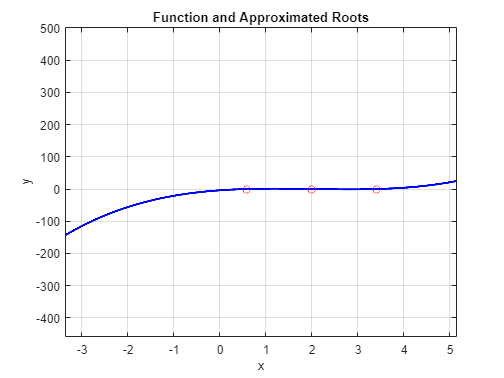


% Plot the function and the roots
x_vals = -10:0.001:10;
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b', 'LineWidth', 2);
hold on;
scatter(roots, zeros(size(roots)), 'ro');
xlabel('x');
ylabel('y');
title('Function and Approximated Roots');
grid on;
hold off;

xlim([-3.35 5.14])
ylim([-458 500])

**9.[Preparing Open Method for Use With Closed Method] **Rewrite your script from Q9 to output 3 intervals where the roots are located between.

% Define the function
f = @(x) x^3 - 6*x^2 + 10*x - 4;

% Set step size and range
step = 0.1;
x_range = -10:step:10;

% Initialize variables
intervals = cell(1, 3);
prev_x = x_range(1);
prev_y = f(prev_x);

% Iterate through the x range
for x = x_range
    y = f(x);
    
    % Check for sign change (possible interval with root)
    if y * prev_y < 0
        interval_start = prev_x;
        interval_end = x;
        
        % Determine which interval the root belongs to
        interval_index = find(cellfun('isempty', intervals), 1);
        if ~isempty(interval_index)
            intervals{interval_index} = [interval_start, interval_end];
        end
    end
    
    prev_x = x;
    prev_y = y;
end

% Display the intervals
for i = 1:3
    fprintf('Interval %d: [%.4f, %.4f]\n', i, intervals{i}(1), intervals{i}(2));
end

Interval 1: [0.5000, 0.6000]
Interval 2: [3.4000, 3.5000]


Index exceeds the number of array elements. Index must not exceed 0.


% Plot the function and the intervals
x_vals = -10:0.01:10;
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b', 'LineWidth', 2);
hold on;
for i = 1:3
    interval = intervals{i};
    plot(interval, [0, 0], 'r', 'LineWidth', 2);
end
xlabel('x');
ylabel('y');
title('Function and Intervals with Roots');
grid on;
hold off;

**10.[Generalising Method to Any Function]** Write a Matlab function file that implements the Incremental Search Method. The user should be able to input a function f(x), step size h, and range of values to search between [x0,xend]. The output should be a list of brackets (intervals) containing each root. Test your function with the function f(x) = sin(10x) + cos(3x) on the interval [3, 6] with step sizes of 0.06 and 0.03.

% incremental_search.m

% Test the incremental_search function with f(x) = sin(10x) + cos(3x)
f = @(x) sin(10*x) + cos(3*x);
x0 = 3;
xend = 6;
step1 = 0.06;
step2 = 0.03;

intervals1 = incremental_search(f, x0, xend, step1);
intervals2 = incremental_search(f, x0, xend, step2);

% Display the intervals
disp('Intervals with roots (step size 0.06):');

Intervals with roots (step size 0.06):


disp(intervals1);

    {[3.2400 3.3000]}    {[3.3600 3.4200]}    {[3.7200 3.7800]}    {[4.2000 4.2600]}    {[4.2600 4.3200]}    {[4.6800 4.7400]}    {[5.6400 5.7000]}



disp('Intervals with roots (step size 0.03):');

Intervals with roots (step size 0.03):


disp(intervals2);

    {[3.2400 3.2700]}    {[3.3600 3.3900]}    {[3.7200 3.7500]}    {[4.2000 4.2300]}    {[4.2600 4.2900]}    {[4.7100 4.7400]}    {[5.1600 5.1900]}    {[5.1900 5.2200]}    {[5.6700 5.7000]}




function intervals = incremental_search(f, x0, xend, step)
    % Initialize variables
    intervals = {};
    prev_x = x0;
    prev_y = f(prev_x);

    % Iterate through the range
    for x = x0:step:xend
        y = f(x);

        % Check for sign change (possible interval with root)
        if y * prev_y < 0
            interval_start = prev_x;
            interval_end = x;
            intervals{end+1} = [interval_start, interval_end];
        end

        prev_x = x;
        prev_y = y;
    end
end